% example 1: nonstationary data (each variable is continuous & one-dimensional)
clear all,clc,close all
addpath(genpath(pwd))
rng(10)

## generate the data

x1->x2->x3->x4, and the causal modules of x2 and x4 is nonstationary, and their changes are related

T = 500;
x1 = randn(T,1);
x2 = 0.8*x1 + 1.5*sin([1:T]'/50) + 0.5*randn(T,1);
x3 = 0.8*x2 + 0.5*randn(T,1);
x4 = 0.8*x3 + (sin([1:T]'/50)+sin([1:T]'/20)) + 0.5*randn(T,1);
Data = [x1,x2,x3,x4];



## **Plot data**

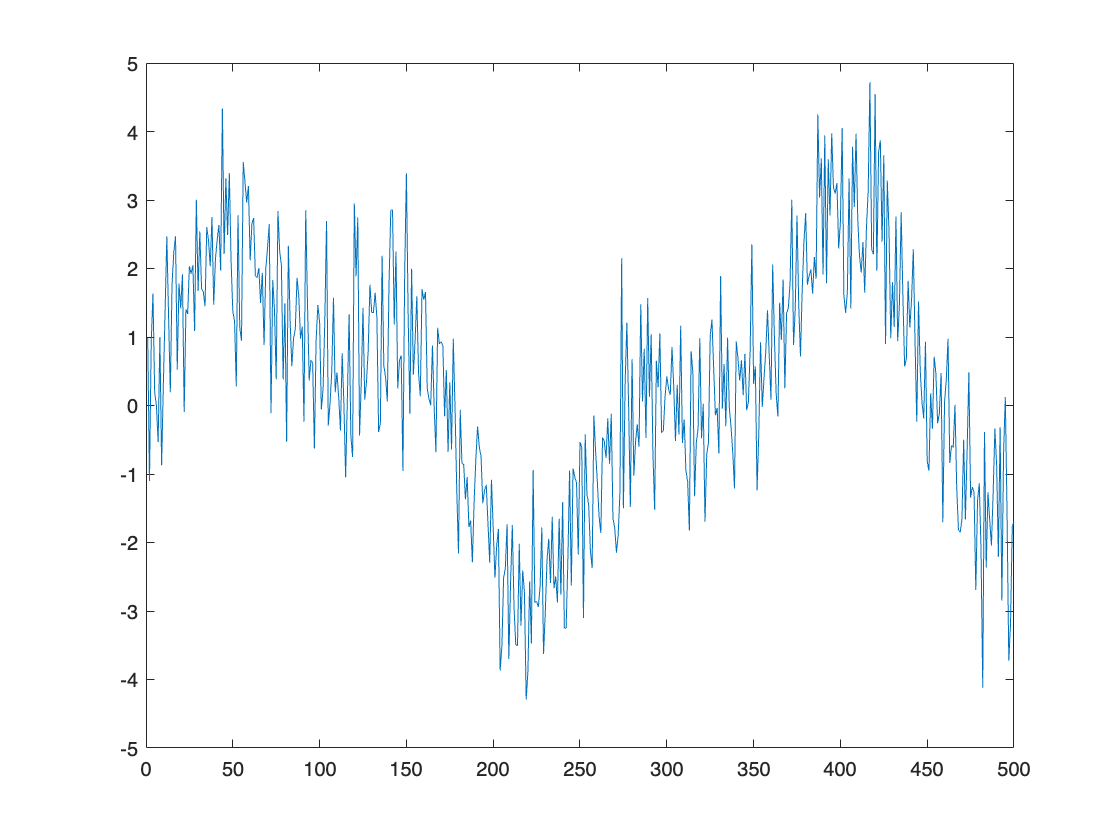

figure
plot(x4)

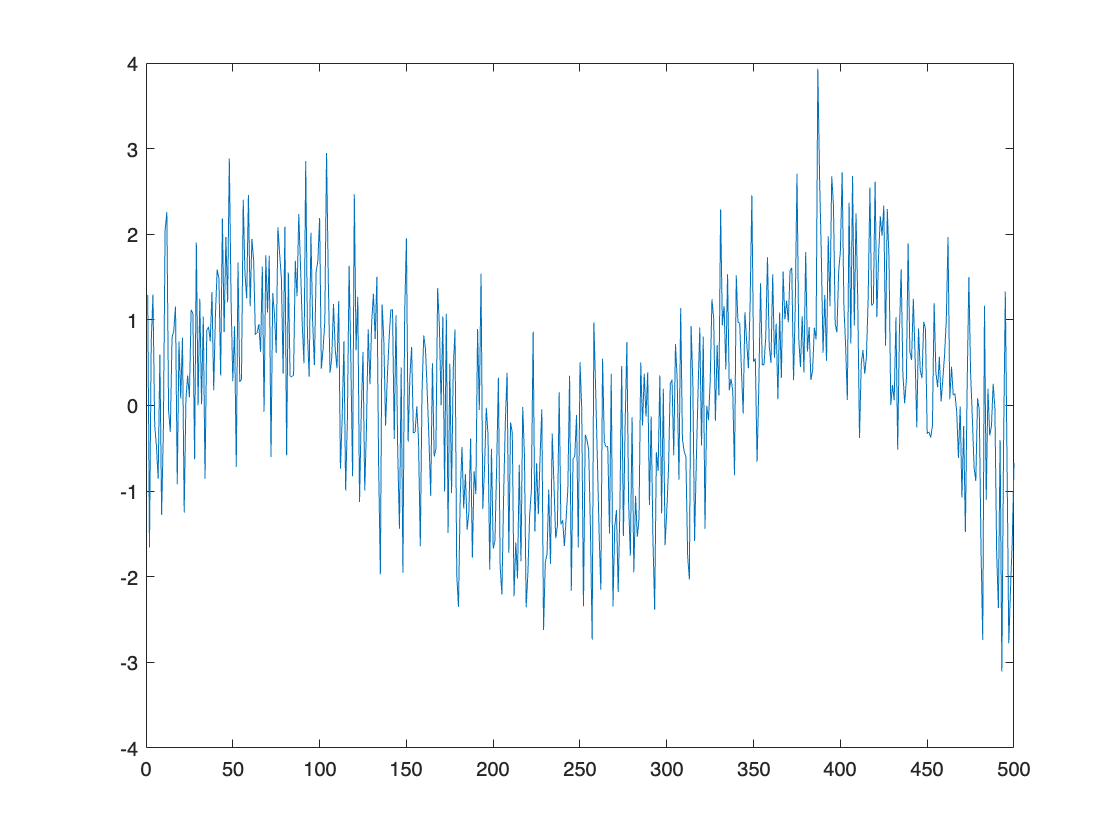

figure
plot(x3)

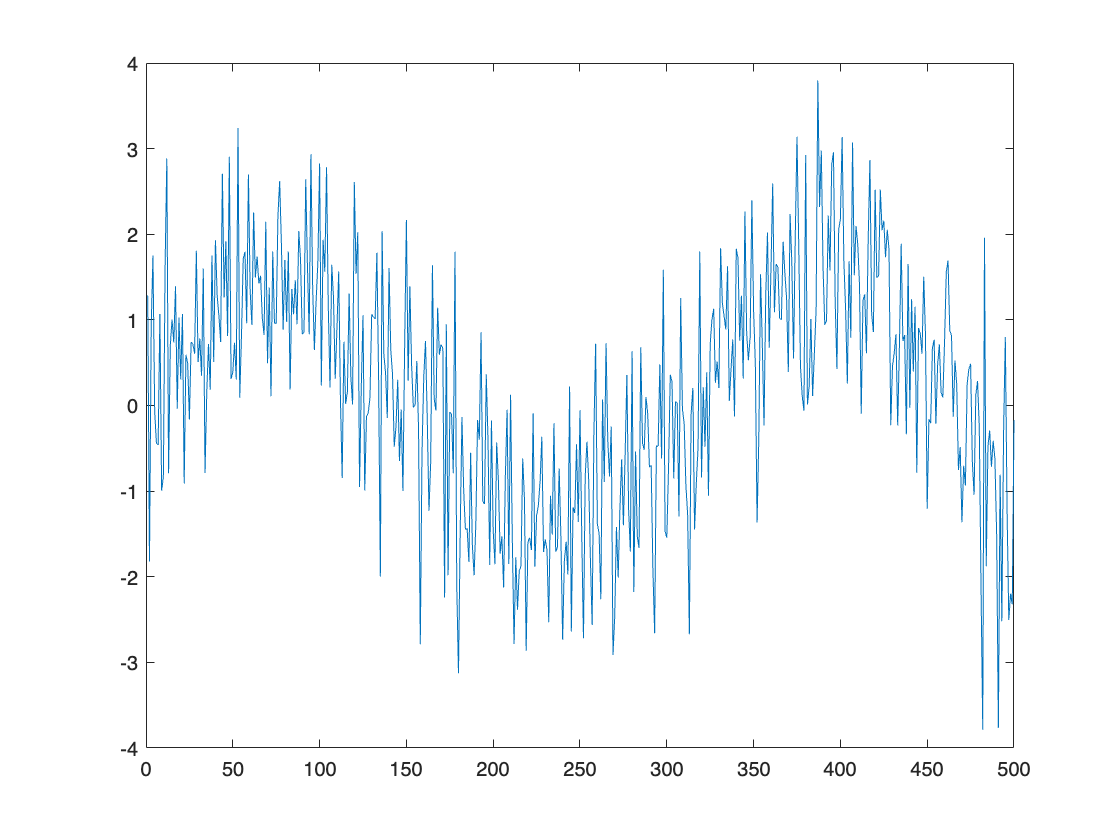

figure
plot(x2)

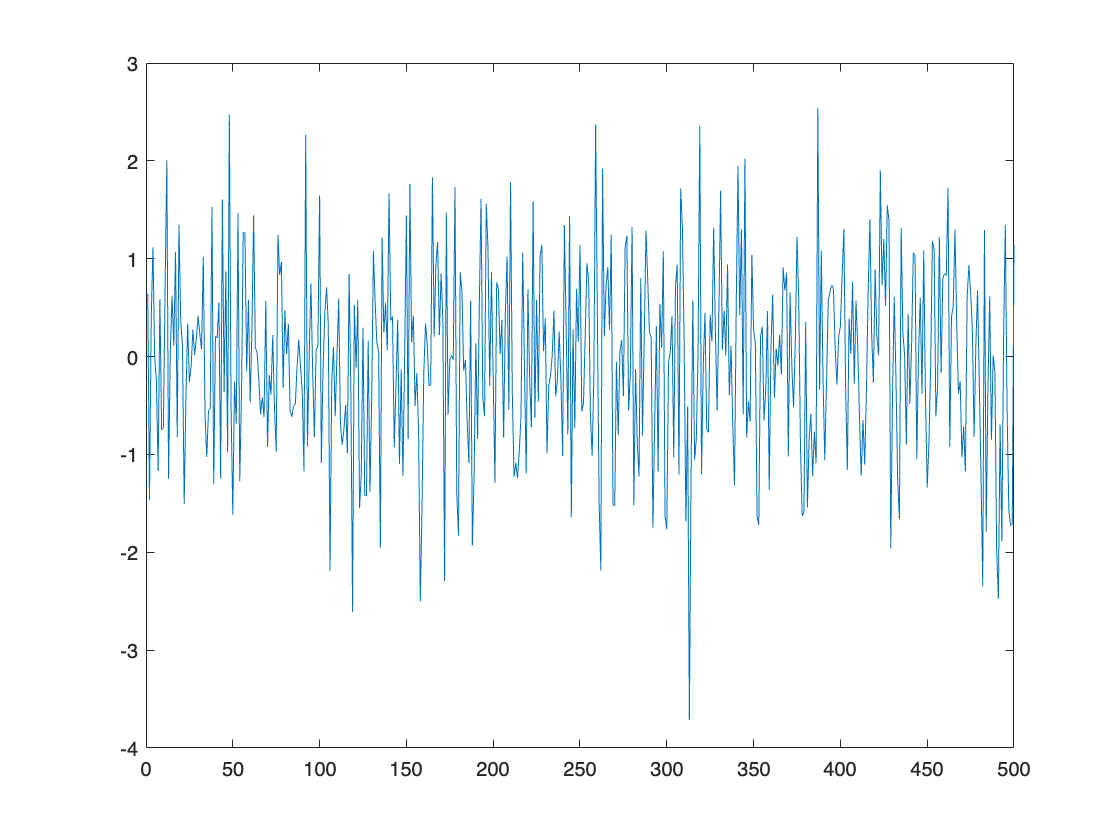

figure
plot(x1)

## set the parameters

alpha = 0.05; % signifcance level of independence test
maxFanIn = 2; % maximum number of conditional variables
if (T<=1000) % for small sample size, use GP to learn the kernel width in conditional independence tests
    cond_ind_test='indtest_new_t';
    IF_GP = 1;
else
    if (T>1000 & T<=2000) % for relatively large sample size, fix the kernel width
        cond_ind_test='indtest_new_t';
        IF_GP = 0;
    else % for very large sample size, fix the kernel width and use random fourier feature to approximate the kernel
        cond_ind_test='indtest_new_t_RFF';
        IF_GP = 0;
    end
end
pars.pairwise = false;
pars.bonferroni = false;
pars.if_GP1 = IF_GP; % for conditional independence test, whether use GP to learn the kernel width
pars.if_GP2 = 1;  % for direction determination with independent change principle & nonstationary driving force visualization
pars.width = 0; % kernel width on observational variables (except the time index). If it is 0, then use the default kernel width when IF_GP = 0
pars.widthT = 0.1; % the kernel width on the time index
c_indx = [1:T]'; % surrogate variable to capture the distribution shift;
% here it is the time index, because the data is nonstationary
Type = 1;
% If Type=0, run all phases of CD-NOD (including
%   phase 1: learning causal skeleton,
%   phase 2: identifying causal directions with generalization of invariance,
%   phase 3: identifying directions with independent change principle, and
%   phase 4: recovering the nonstationarity driving force )
% If Type = 1, perform phase 1 + phase 2 + phase 3
% If Type = 2, perform phase 1 + phase 2
% If Type = 3, only perform phase 1

## run CD-NOD

[g_skeleton, g_inv, gns, SP] = nonsta_cd_new(Data, cond_ind_test, c_indx, maxFanIn, alpha, Type, pars);